# **Sesión 1.- Cinemática de robots**

**Cinemática directa:** Dada una configuración articular, halla la posición y orientación de alguna parte del robot.

- En Matlab mediante la función [getTransform](https://es.mathworks.com/help/robotics/ref/rigidbodytree.gettransform.html?s_tid=doc_ta)

**Cinemática inversa:** Halla la configuración articular necesaria para alcanzar una posición y orientación de alguna parte del robot.

- En Matlab Utilización del objeto [inverseKinematics](https://es.mathworks.com/help/robotics/ref/inversekinematics-system-object.html?searchHighlight=inverseKinematics&s_tid=srchtitle_inverseKinematics_1) (a partir del pose) o .[`generalizedInverseKinematics`](https://es.mathworks.com/help/robotics/ref/generalizedinversekinematics-system-object.html?searchHighlight=generalizedInverseKinematics%20&s_tid=srchtitle_generalizedInverseKinematics%20_1) (a partir de la definición de una o varias restricciones)

- EStos métodos utilizan un alogirmto (`BFGSGradientProjection o LevenbergMarquardt) `para resolver la cinemática inversa.

- La resolución no es sistematica, puede haber múltiples soluciones. 

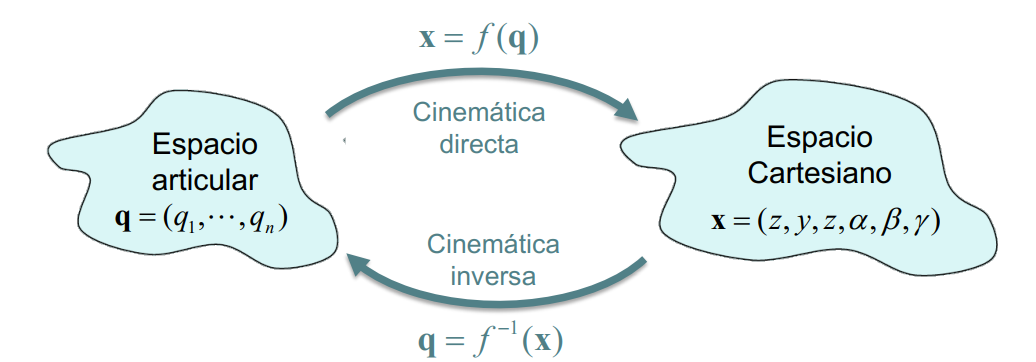

En aplicaciones robóticas, se pueden utilizar muchos sistemas de coordenadas diferentes para definir dónde se encuentran los robots, sensores y otros objetos. En general, la ubicación de un objeto en el espacio 3D se puede especificar mediante valores de posición y orientación. Hay varias representaciones posibles para estos valores, algunas de las cuales son específicas de ciertas aplicaciones. Para más información sobre las representaciones posibles en Matlab, ver el siguiente enlace: [https://es.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html](https://es.mathworks.com/help/robotics/ug/coordinate-transformations-in-robotics.html)

**Definición de la posición y orientación del efector final medainte la matriz de transformación homogénea**

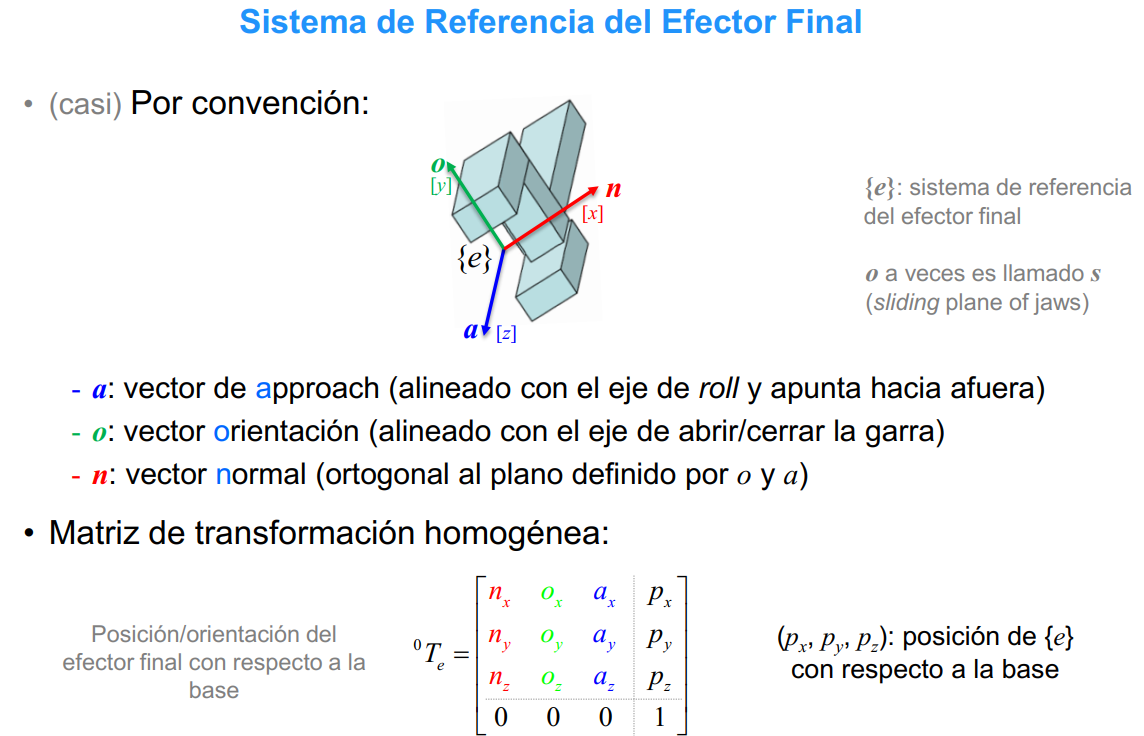

Las funicones que veremos en este ejemplo para definir la matriz de transformación homogénea del efector final son las siguientes:

- Definición de la posición mediante la función [trvec2tform](https://es.mathworks.com/help/robotics/ref/trvec2tform.html?s_tid=doc_ta), que convierte la representación cartesiana de un vector (x,y,z) en la transformación homogénea correspondiente.

- Definición de la orientación mediante la función [axang2tform](https://es.mathworks.com/help/nav/ref/axang2tform.html?searchHighlight=axang&s_tid=srchtitle_axang_3) que convierte una rotación rotación (rad) escalar alrededor de un eje fijo definido por un vector en una matriz de transformación homogénea.

**Cargar robot**

clc;
clear;
close all;
IRB120=loadrobot("abbIrb120",'Gravity',[0 0 -9.81]);
showdetails(IRB120)

--------------------
Robot: (8 bodies)

 Idx     Body Name            Joint Name            Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------            ----------            ----------     ----------------   ----------------
   1          base        base_link-base                 fixed         base_link(0)   
   2        link_1               joint_1              revolute         base_link(0)   link_2(3)  
   3        link_2               joint_2              revolute            link_1(2)   link_3(4)  
   4        link_3               joint_3              revolute            link_2(3)   link_4(5)  
   5        link_4               joint_4              revolute            link_3(4)   link_5(6)  
   6        link_5               joint_5              revolute            link_4(5)   link_6(7)  
   7        link_6               joint_6              revolute            link_5(6)   tool0(8)  
   8         tool0          joint6-tool0                 fixed            link_6

endEffector = 'tool0';

# Cinemática directa

**Determinación de la posicion en el espacio cartesiano del efector final y su orientación tomando como referencia la base del robot a partir de las posiciones articulares del robot.**

q0 = homeConfiguration(IRB120)  %Configuración home

q0 = 1×6 struct array with fields:
    JointName
    JointPosition


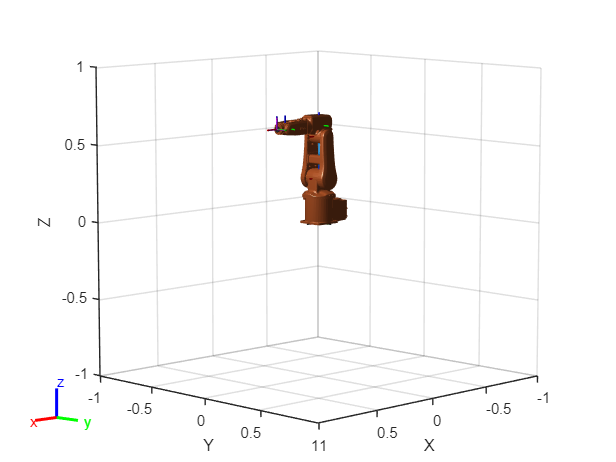

show (IRB120, q0);   %Muestra al robot con la configuración home

%Calculamos la matriz de transformación homogénea del end-effector respecto a la base del robot para la
%confgiguracion articular q0
MTH0 = getTransform(IRB120, q0, endEffector)

MTH0 =     1.0000         0         0    0.3740
         0    1.0000         0         0
         0         0    1.0000    0.6300
         0         0         0    1.0000


**Determinación de la posicion en el espacio cartesiano del efector final tomando como referencia el link_2 a partir de las posiciones articulares del robot generadas de manera aleatoria:**

randConfig = IRB120.randomConfiguration  %Configuración aleatoria

randConfig = 1×6 struct array with fields:
    JointName
    JointPosition


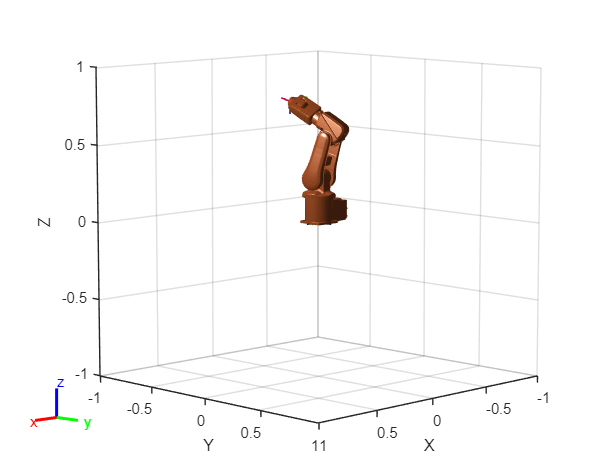

show (IRB120, randConfig);   %Mostramos el robot

%Calculamos la matriz de transformación homogénea del end-effector respecto a la base del robot para la
%confgiguracion articular randConfig
MTHRandom = getTransform(IRB120, randConfig, endEffector)

MTHRandom =     0.0243   -0.9918   -0.1255    0.0384
   -0.9766    0.0033   -0.2153   -0.2195
    0.2139    0.1278   -0.9685    0.7687
         0         0         0    1.0000


**Determinación de la posicion y orientación del efector final tomando como referencia el eslabón 2 (link_2) a partir de las posiciones articulares del robot generadas de manera aleatoria:**

MTHRandom_link2 = getTransform(IRB120, randConfig, endEffector, 'link_2')

MTHRandom_link2 =     0.9750   -0.1921   -0.1115    0.3524
   -0.2095   -0.9623   -0.1733   -0.0151
   -0.0740    0.1923   -0.9785    0.3929
         0         0         0    1.0000


# Cinemática inversa

Define un objeto `inverseKinematics `para crear un solver de cinemática inversa para calcular la configuración articular para alcanzar una pose la pose del efector final deseada. El objeto `inverseKinematics `debe asociarse a un modelo `rigidBody, en este caso el IRB120.`

ik = inverseKinematics('RigidBodyTree',IRB120);

Especifica una conjetura inciial de configuración (`initialguess`), en este caso, la posición de home. Además, define los pesos (`weights`) de las tolerancias de las seis componentes de la pose (los tres primeros elementos corresponden al error en la orientación y los tres ultimos, al error en la posición). Por ejemplo, si lo que  interesa es alcanzar una posición concreta e importa menos su orientación, utiliza pesos de menor magnitud para los angulos que para las posiciones. 

weights = [0.25 0.25 0.25 1 1 1];
initialguess = IRB120.homeConfiguration;

Utiliza el objeto `ik` para calcular la configuración angular de un eslabón, en este caso, del `endEffector` a partir de su pose, definida por la matriz de transformación homogénea `MTHRandom.`

MTHRandom

MTHRandom =     0.0243   -0.9918   -0.1255    0.0384
   -0.9766    0.0033   -0.2153   -0.2195
    0.2139    0.1278   -0.9685    0.7687
         0         0         0    1.0000


[configSoln,solnInfo] = ik(endEffector,MTHRandom,weights,initialguess);
configSoln

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


Muestra la nueva configuración de solución generada. La solución es una configuración de articulaciones ligeramente diferente que consigue la misma posición del efector final. Múltiples llamadas al objeto ik pueden dar configuraciones de articulaciones similares o muy diferentes.

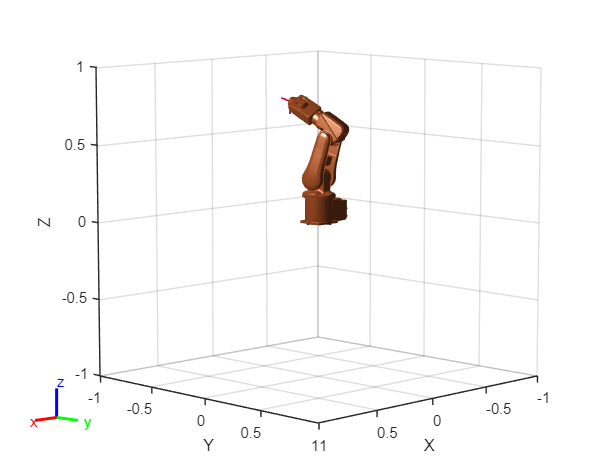

show(IRB120,configSoln);

`solnInfo `proporcoina información sobre la búsqueda:

solnInfo

solnInfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9148e-10
             ExitFlag: 1
               Status: 'success'


# Cinemática inversa - Definición de la posicíon del end-effector

Definimos la posición y la orientación del end-effector

x = 0.3;
y = 0.1;
z =0.4;
ang=0.88;

Calculamos la matriz de transformación asociada a la pose (posición y orientación) definida para poder calcular la cinemática inversa.

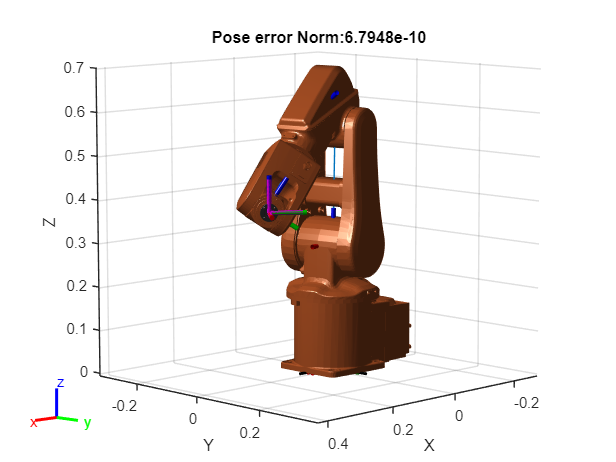

MTH = trvec2tform ([x y z])*axang2tform ([0 0 1 ang]); %respecto al ángulo Z
%MTH = trvec2tform ([x y z])*axang2tform ([0 1 0 ang]);  %respecto al ángulo Y
[configSoln,solnInfo] = ik(endEffector,MTH,weights,initialguess);
show(IRB120,configSoln);
axis auto;
%Mostramos por pantalla la información de la solución generada por la cinemática inversa. 
%Algunas combinaciones pueden salir fuera del espacio de trabajo del robot.
title (strcat ('Pose error Norm: ', num2str(solnInfo.PoseErrorNorm)));

# Cinemática inversa con restricciones

Crear el objeto para resolver la cinemática inversa

gik = generalizedInverseKinematics;

Configura el objeto para usar el robot IRB120.

gik.RigidBodyTree = IRB120;

Especifica las restricciones. Las restricciones que puedes imponer son las siguietnes:

- `'orientation'` — [`constraintOrientationTarget`](https://es.mathworks.com/help/robotics/ref/constraintorientationtarget.html)

- `'position'` — [`constraintPositionTarget`](https://es.mathworks.com/help/robotics/ref/constraintpositiontarget.html)

- `'pose'` — [`constraintPoseTarget`](https://es.mathworks.com/help/robotics/ref/robotics.constraintposetarget.html)

- `'aiming'` — [`constraintAiming`](https://es.mathworks.com/help/robotics/ref/constraintaiming-class.html)

- `'cartesian'` — [`constraintCartesianBounds`](https://es.mathworks.com/help/robotics/ref/constraintcartesianbounds.html)

- `'joint'` — [`constraintJointBounds`](https://es.mathworks.com/help/robotics/ref/constraintjointbounds.html)

Especificamos las restricciones:

- El origen del end-effector esta a `[0.0 0.5 0.5]` relativo a la base del robot

- El eje Z del end-effector apunta hacia el origen de la base del robot

Definimos las restricciones que imponemos al solucionador..

gik.ConstraintInputs = {'position','aiming'};

posTgt = constraintPositionTarget(endEffector);
posTgt.TargetPosition = [0.0 0.5 0.5];

aimCon = constraintAiming(endEffector);
aimCon.TargetPoint = [0.0 0.0 0.0];

Cálculo de la cinemática inversa consdierando las restricciones impuestas. Visualización de la solución. 

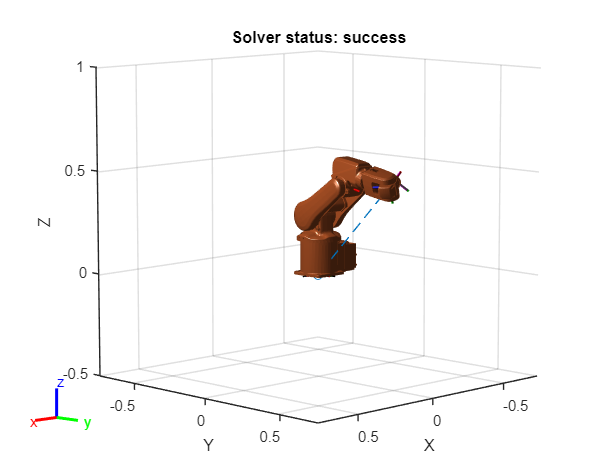

%Cinemática inversa
q0 = homeConfiguration(IRB120); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon);

%Visualización
show(IRB120,q);
title(['Solver status: ' solutionInfo.Status])
axis([-0.75 0.75 -0.75 0.75 -0.5 1])
hold on
plot3([0.0 0.0],[0.5 0.0],[0.5 0.0],'--o')
hold off